%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% CODE CHALLENGE 4 - Linear Least-Squares Fit
%
% The purpose of this program is to calculate the equation of the best fit
% line for a data set using linear least-squares fitting.
%
% To complete the challenge, finish the code below to:
% 1) load data from csv file
% 2) find linear best fit coefficients and associated uncertainty
% 3) plot the original data along with the best fit line 
% 4) add errorbars for fit uncertainty to this plot from the data and from
%    the linear regression parameters
%
% NOTE: DO NOT change any variable names already present in the code.
% 
% Upload your team's script to Gradescope when complete.
% 
% NAME YOUR FILE AS Challenge4_Sec{section number}_Group{group breakout #}.m 
% ***Section numbers are 1 or 2*** 
% EX File Name: Challenge4_Sec1_Group15.m 
%
% STUDENT TEAMMATES
% 1) Tristan Workman
% 2) Daniel Smith
% 3) Joseph Charles Miserlian
% 4) Nathan Brock Sharp
% 5) Kyle Komarnitsky
% Group: 22
% 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Housekeeping (Please don't "clear all" or "clearvars", it makes grading difficult)

close all   % Close all open figure windows
clc           % Clear the command window

## Load and extract the time and velocity vectors from the data

data = readtable("Challenge4_data.csv");

t = data.Time_s_;    % [s]
v = data.Velocity_m_s_;    % [m/s]

## Calculations

Find number of data points in the vectors

N = length(t);

% Find linear best fit coefficients A and B
% Create H matrix
H = [ones(length(v),1),t];

% Create y matrix
y = v;

% Create W matrix (hint: type <help diag> in command line)
holder = ones(length(t),1) .* (1/(0.1)^2);
W = diag(holder);

% Solve for P matrix
P = (H' * W * H)^-1;

% Solve for x_hat matrix and extract A and B parameters
x_hat = ((H' * W * H)^-1) * H' * W * y;
A = x_hat(1);
B = x_hat(2);

% extract uncertainty in A and uncertainty in B from P matrix
A_error = sqrt(P(1,1));
B_error = sqrt(P(2,2));

## Display acceleration with associated uncertainty and the intial velocity with associated uncertainty

disp("Acceleration: " + round(B,2) + " +- " + round(B_error,3))

Acceleration: -1.52 +- 0.05


disp("Initial Velocity: " + round(A,1) + " +- " + round(A_error,1))

Initial Velocity: 8.2 +- 0.3


## Find predicted velocity values using your linear fit equation

v_predicted = A + (B .* t);

## Ploting and Error Calculations

On the same plot, do the following: 1. plot the velocity data vs time as a scatter plot 2. plot predicted velocity vs time as a line 3. title your plot so that it indicates what celestial body this data simulates 4. Add measured velocity error bars and predicted velocity error bars to the plot (hint - this will involve error propagation calculations

scatter(t,v)
xlabel("Time")
ylabel("Velocity")

v_err = 0.1

v_err = 0.1000

v_predicted_error = sqrt(sum(diag(P)))

v_predicted_error = 0.2745

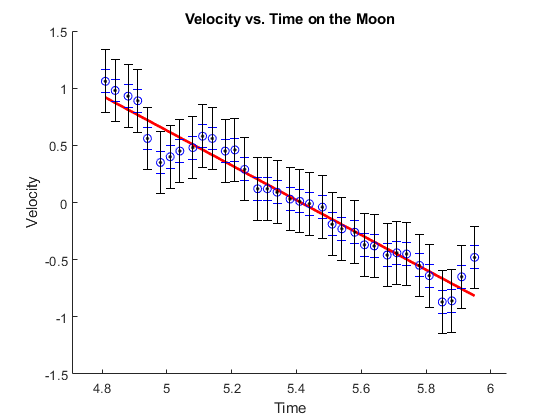


v_err_m = 0.1 * (ones(35,1));
v_predicted_error_m = v_predicted_error * (ones(35,1));

title("Velocity vs. Time on the Moon")
hold on
plot(t,v_predicted,'r',"LineWidth",2)
hold on
errorbar(t,v,v_err_m,"bo")
hold on
errorbar(t,v,v_predicted_error_m,"k.")
xlim([(min(t)-0.1) (max(t)+0.1)])

We gathered that the slope of our velocity vs. time data (acceleration) was closest to the acceleration due to gravity on the moon (1.52 m/s^2 vs 1.62 m/s^2).